In this mlx script we solve task2 (the implementation) of the first exercise sheet. (Submitted by Thomas Stegmeyer, Matthias Gültig, Sven Ullmann).

We start by initializing the constant values. 

clf;
simtime = 5;
dt = 0.01;
m1 = 2.1;
m2 = 1.65; 
l1 = 0.335; 
l2 = 0.263; 
d1 = 0.146; 
d2 = 0.179; 
I1 = 0.024;
I2 = 0.02;

For the first given start values we obtain the following results 

disp('First start values:')

First start values:


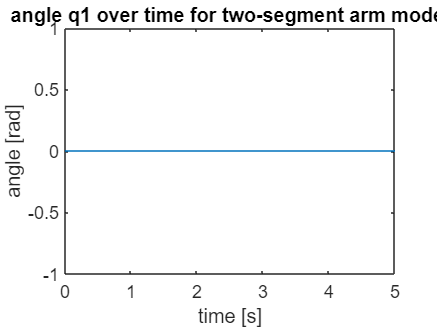


q0_start = 0;
q1_start = 0;
q0_point_start = 0;
q1_point_start = 0; 
u0_start = 0;
u1_start = 0;

q = integrate_euler(simtime,dt,m1,m2,l1,l2,d1,d2,I1,I2,q0_start, q1_start, q0_point_start, q1_point_start, u0_start, u1_start);
x = 0:dt:5;

figure(1)
plot(x,q(1,:));
xlabel('time [s]');
ylabel('angle [rad]');
title('angle q1 over time for two-segment arm model');

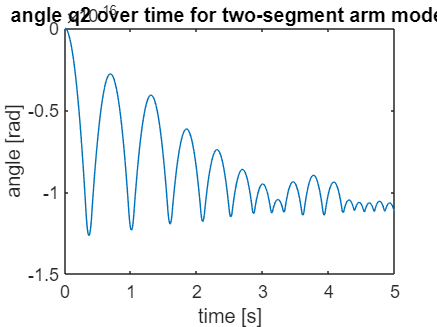


figure(2)
plot(x,q(2,:));
xlabel('time [s]');
ylabel('angle [rad]');
title('angle q2 over time for two-segment arm model');

For the second start values we obtain: 

disp("Second start values:")
q0_start = 0.35;
q1_start = 0;
q0_point_start = 0;
q1_point_start = 0; 
u0_start = 0;
u1_start = 0;

q = integrate_euler(simtime,dt,m1,m2,l1,l2,d1,d2,I1,I2,q0_start, q1_start, q0_point_start, q1_point_start, u0_start, u1_start);
x = 0:dt:5;

figure(3)
plot(x,q(1,:));
xlabel('time [s]');
ylabel('angle [rad]');
title('angle q1 over time for two-segment arm model');

figure(4)
plot(x,q(2,:));
xlabel('time [s]');
ylabel('angle [rad]');
title('angle q2 over time for two-segment arm model');

For the third start values we obtain:

disp("Third start values:")
q0_start = 0;
q1_start = 0;
q0_point_start = 0;
q1_point_start = 0; 
u0_start = 1;
u1_start = 0;

q = integrate_euler(simtime,dt,m1,m2,l1,l2,d1,d2,I1,I2,q0_start, q1_start, q0_point_start, q1_point_start, u0_start, u1_start);
x = 0:dt:5;

figure(5)
plot(x,q(1,:));
xlabel('time [s]');
ylabel('angle [rad]');
title('angle q1 over time for two-segment arm model');

figure(6)
plot(x,q(2,:));
xlabel('time [s]');
ylabel('angle [rad]');
title('angle q2 over time for two-segment arm model');